### Aproximarea sistemului printr-un proces de ordin I cu timp mort

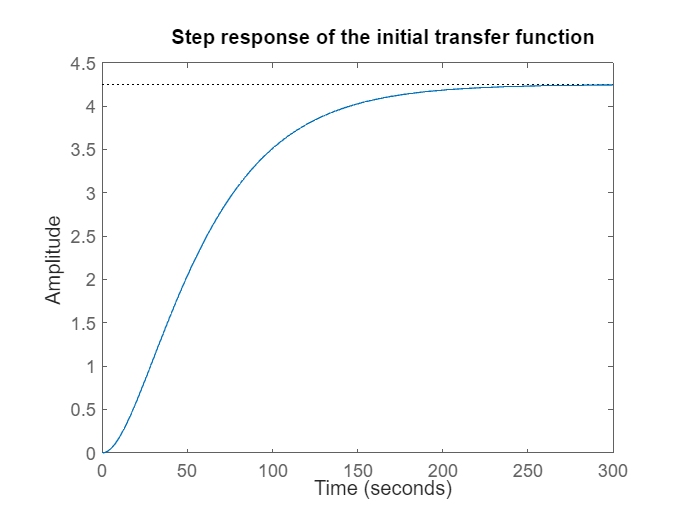

Hf3 = tf(4.25, conv(conv([0.3 1], [22.5 1]), [40 1]));
figure, 
step(Hf3);
title('Step response of the initial transfer function')

- **Metoda tangentei**

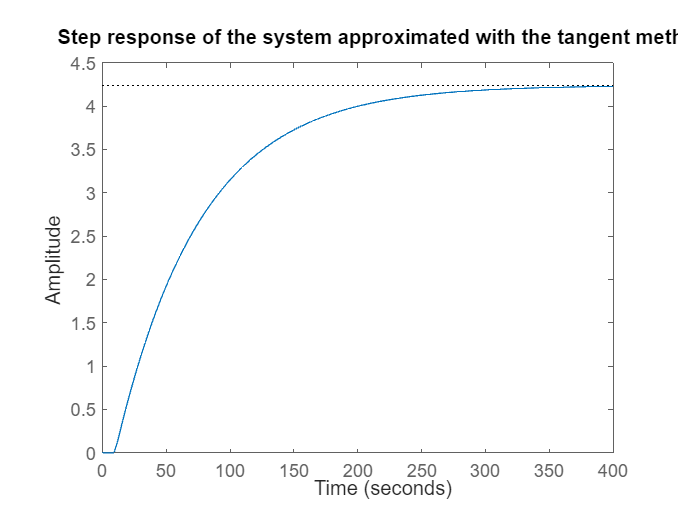

y_stationar = 4.24;
y0 = 0;

m_stationar = 1;
m0 = 0;

k = (y_stationar - y0) / (m_stationar - m0);
T_tangeta = 66.4;
Tm1 = 9.87;

T_esantion1 = 15;

H_tangenta = tf(k, [T_tangeta 1], 'IOdelay', Tm1);
step(H_tangenta)
title('Step response of the system approximated with the tangent method')

- **Metoda Cohen-Coon**

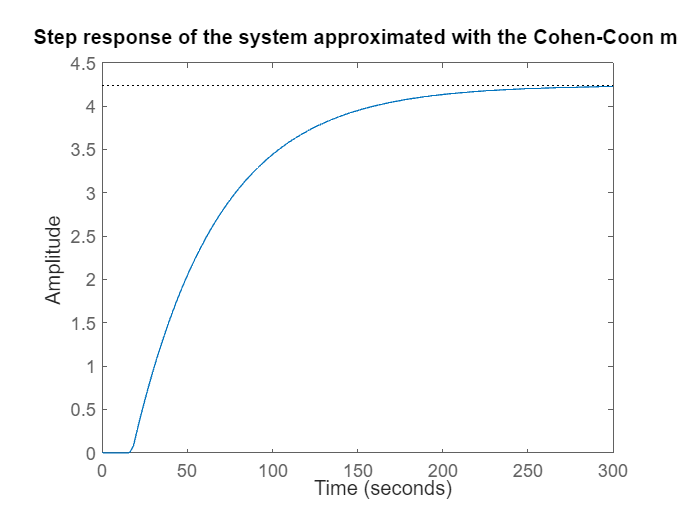

% m_stationar632 = 0.632 * y_stationar; % t = 66.4
% m_stationar28 = 0.28 * y_stationar; % t = 33.8;
t632 = 66.8;
t28 = 33.8;
T_CC = 1.5 * (t632 - t28);
Tm2 = 1.5 * (t28 - 1/3 * t632);
alpha = T_CC/Tm2;
T_esantion2 = 20;

H_CC = tf(k, [T_CC 1], 'IOdelay', Tm2);
step(H_CC)
title('Step response of the system approximated with the Cohen-Coon method')

### Calculul regulatoarelor cu metoda Chien-Hrones-Reswich

- **Raspuns optim in raport cu referinta**

% P
Pr = 0.3 * T_tangenta / (Tm1 * k)

Pr = 0.4760

% PI
Kr_PI_chr = 0.35 * T_tangenta / (Tm1 * k);
Ti_PI_chr = 1.2 * Tm1;
PIr = Kr_PI_chr * tf([Ti_PI_chr 1], [Ti_PI_chr 0])

PIr =
 
  6.577 s + 0.5553
  ----------------
      11.84 s
 
Continuous-time transfer function.
Model Properties


% PID
Kr_PID_chr1 = 0.6 * T_tangenta / (Tm1 * k);
Ti_PID_chr1 = Tm1;
Td_chr1 = 0.5 * Tm1;

% q = 1
PID_q1r = Kr_PID_chr1 * (tf(Td_chr1, Ti_PID_chr1) + tf(1, [Ti_PID_chr1 0]) + tf([Td_chr1 0], [T_tangenta 1]))

PID_q1r =
 
  3537 s^2 + 670.3 s + 9.396
  --------------------------
      6468 s^2 + 97.42 s
 
Continuous-time transfer function.
Model Properties


[num_PID_chr1, den_PID_chr1] = tfdata(PID_q1r, 'v');

% q = 0
PID_q0r = Kr_PID_chr1 * (tf(1, [Ti_PID_chr1 0]) + tf([Td_chr1 0], [T_tangenta 1]))

PID_q0r =
 
  46.37 s^2 + 63.21 s + 0.952
  ---------------------------
      655.4 s^2 + 9.87 s
 
Continuous-time transfer function.
Model Properties


[num_PID_chr0, den_PID_chr0] = tfdata(PID_q0r, 'v');

- **Raspuns optim la perturbatii**

% P
P = 0.3 * T_tangenta / (Tm1 * k)

P = 0.4760

% PI
Kr_PI_chr_p = 0.6 * T_tangenta / (Tm1 * k);
Ti_PI_chr_p = 4 * Tm1;
PI = Kr_PI_chr_p * tf([Ti_PI_chr_p 1], [Ti_PI_chr_p 0])

PI =
 
  37.58 s + 0.952
  ---------------
      39.48 s
 
Continuous-time transfer function.
Model Properties


% PID
Kr_PID_chr1_p = 0.95 * T_tangenta / (Tm1 * k);
Ti_PID_chr1_p = 2.4 * Tm1;
Td_chr1_p = 0.42 * Tm1;

% q = 1
PID_q1 = Kr_PID_chr1_p * (tf(Td_chr1_p, Ti_PID_chr1_p) + tf(1, [Ti_PID_chr1_p 0]) + tf([Td_chr1_p 0], [T_tangenta 1]))

PID_q1 =
 
  1.333e04 s^2 + 2519 s + 35.71
  -----------------------------
     3.726e04 s^2 + 561.1 s
 
Continuous-time transfer function.
Model Properties


[num_PID_chr1_a, den_PID_chr1_a] = tfdata(PID_q1, 'v');

% q = 0
PID_q0 = Kr_PID_chr1 * (tf(1, [Ti_PID_chr1_p 0]) + tf([Td_chr1_p 0], [T_tangenta 1]))

PID_q0 =
 
  93.48 s^2 + 63.21 s + 0.952
  ---------------------------
      1573 s^2 + 23.69 s
 
Continuous-time transfer function.
Model Properties


[num_PID_chr0_a, den_PID_chr0_a] = tfdata(PID_q1, 'v');

### Simulare PID-uri in Simulink

- **Raspuns optim in raport cu referinta**

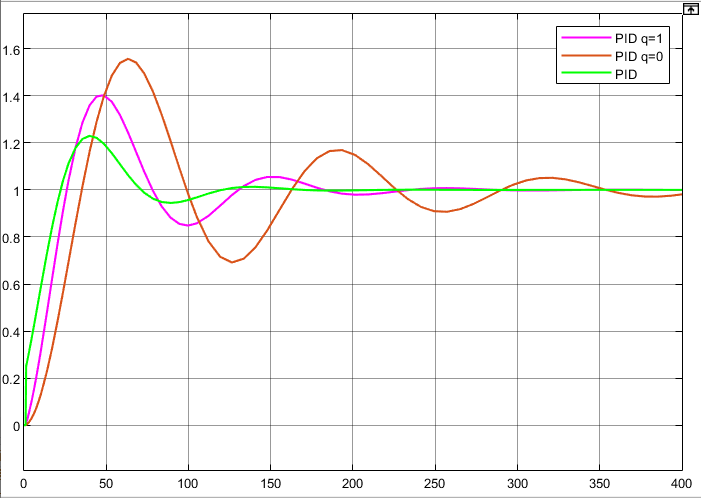

- **Raspuns optim la perturbatii**

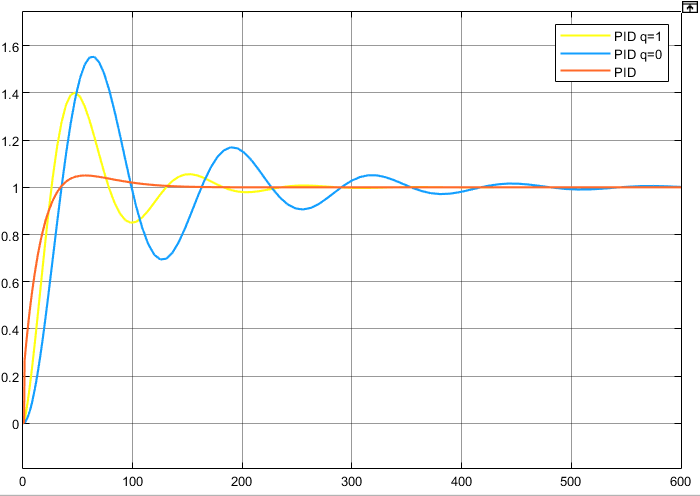

### Simulare raspunsuri sistem cu utilizarea regulatoarelor

- **Raspuns optim in raport cu referinta**

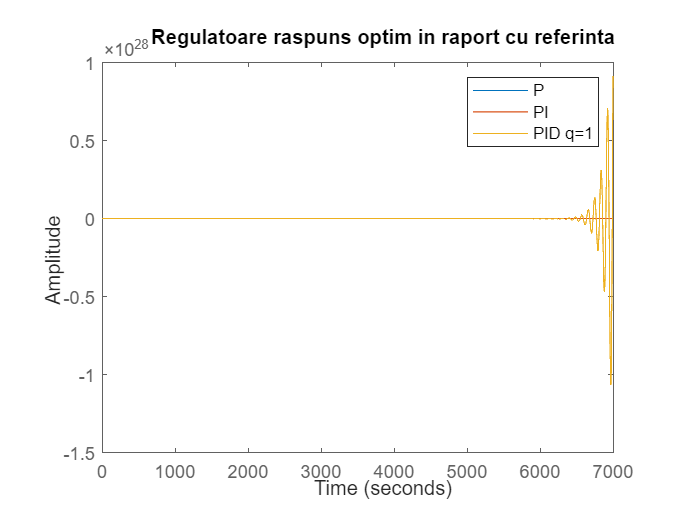

figure,
step(feedback(Hf3*Pr, 1)), hold on
step(feedback(Hf3*PIr, 1)), hold on
step(feedback(Hf3*PID_q1r, 1)), hold off
legend('P', 'PI', 'PID q=1')
title('Regulatoare raspuns optim in raport cu referinta')

- **Raspuns optim la perturbatii**

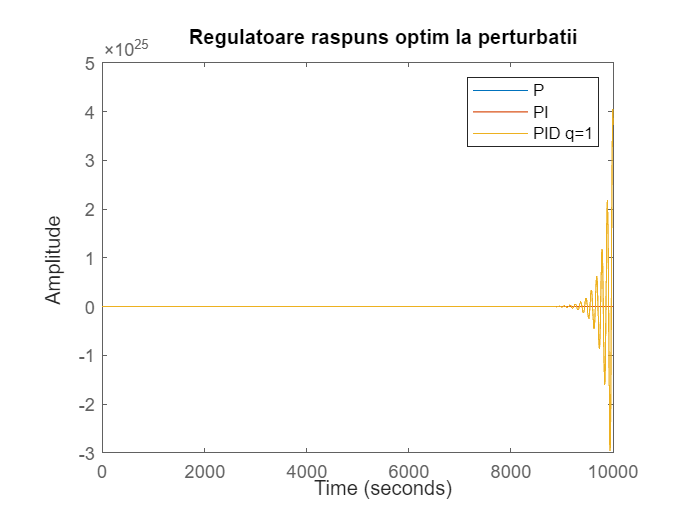

figure,
step(feedback(Hf3*P, 1)), hold on
step(feedback(Hf3*PI, 1)), hold on
step(feedback(Hf3*PID_q1, 1)), hold off
legend('P', 'PI', 'PID q=1')
title('Regulatoare raspuns optim la perturbatii')

### Performante

- Raspuns P

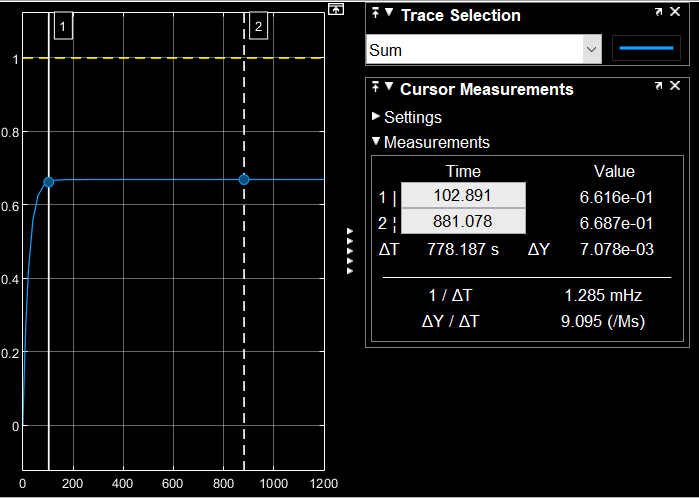

- Raspuns PI

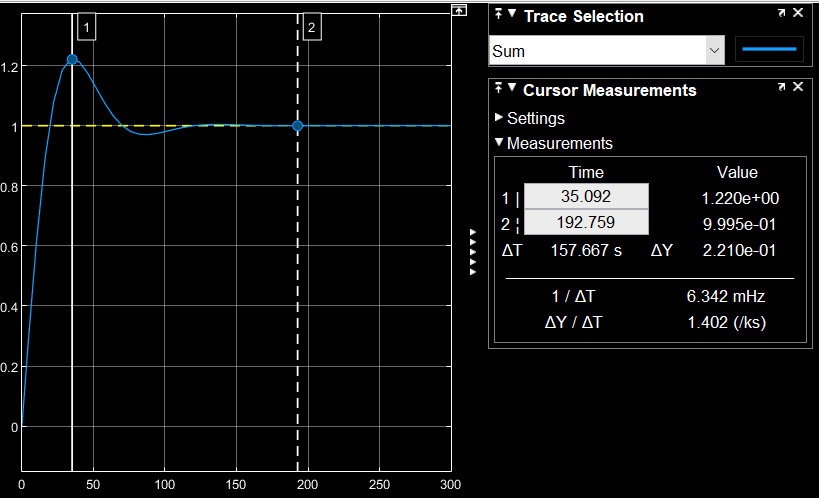

- Raspuns PID q = 1

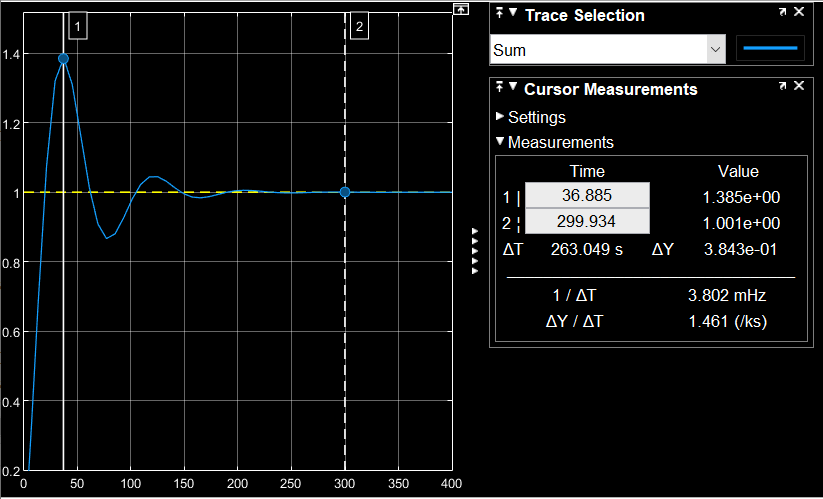

- Raspuns PID q = 0

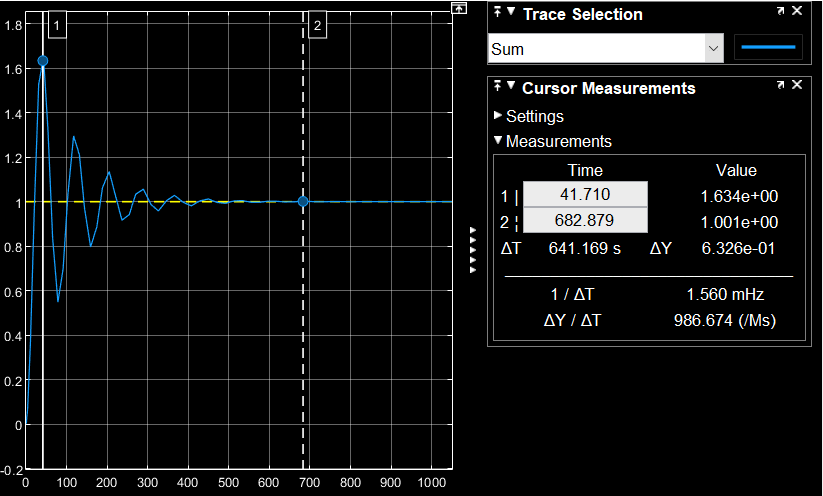

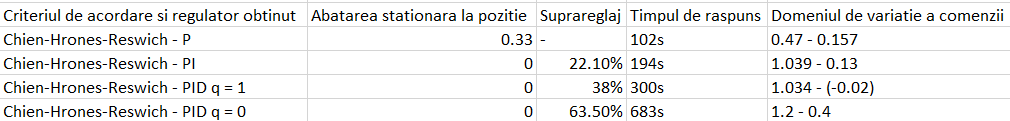

- Raspuns P

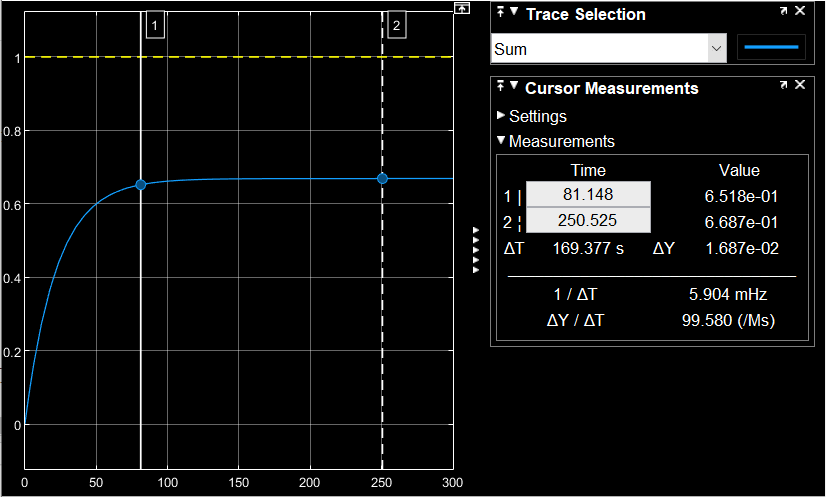

- Raspuns PI

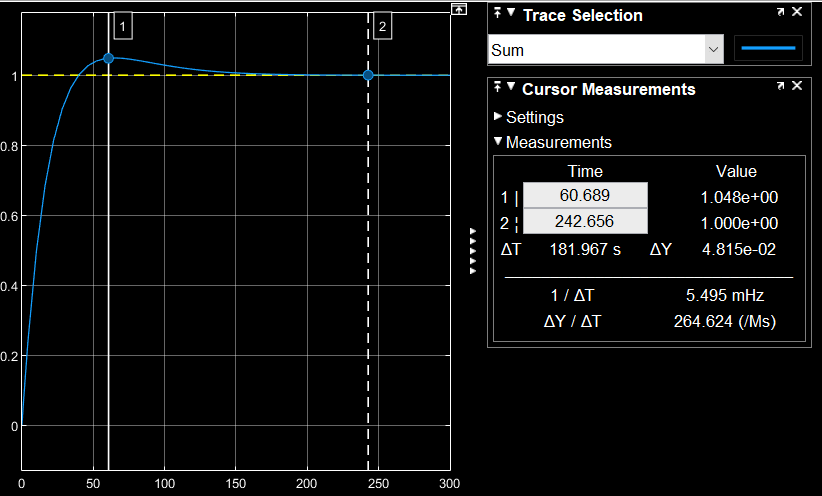

- Raspuns PID q = 1

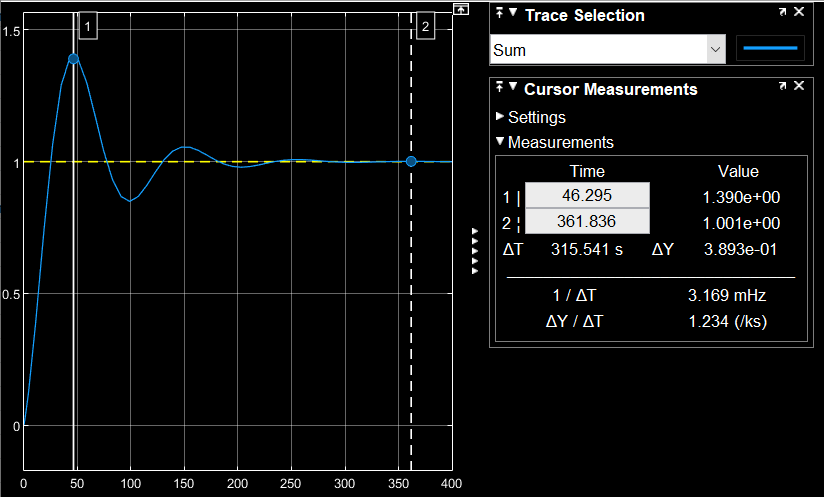

- Raspuns PID q = 0